run InitEqualizerValues % Updates list of variables


## Low Equalizer

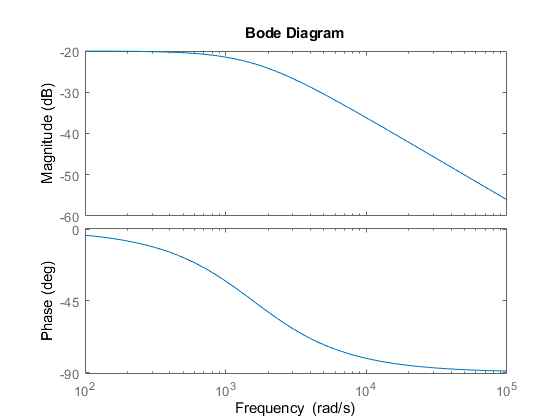

low_gain = 0.1;

low_lowpass = tf(low_gain*fc_lowmid, [1 fc_lowmid]);
hold on
bode(low_lowpass);

## Mid Equalizer

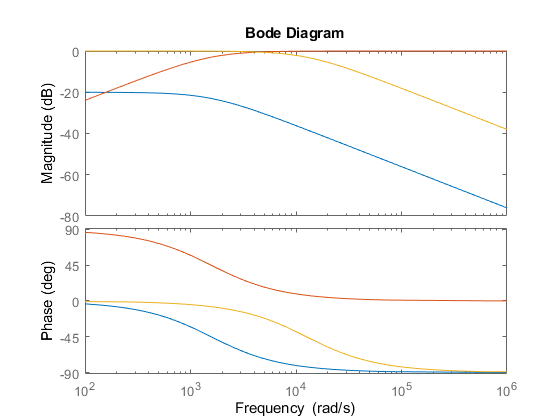

mid_gain = 1;

mid_highpass = tf([mid_gain 0], [1 fc_lowmid]);
mid_lowpass = tf(mid_gain*fc_midhigh, [1 fc_midhigh]);
bode(mid_highpass);
bode(mid_lowpass);

## High Equalizer

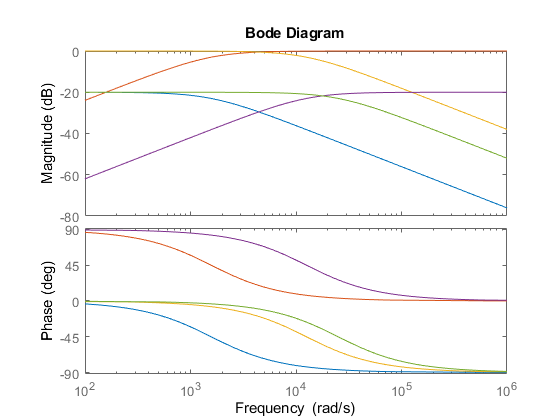

high_gain = 0.1;

high_highpass = tf([high_gain 0], [1 fc_midhigh]);
high_lowpass = tf(high_gain*fc_high, [1 fc_high]);
bode(high_highpass);
bode(high_lowpass);

## Finishing Touches

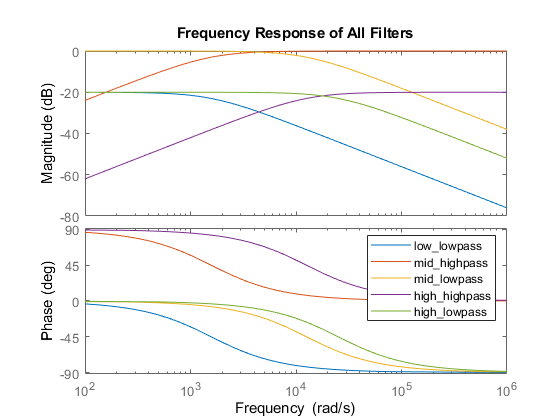

title("Frequency Response of All Filters")
legend
hold off

## Full Open-Loop System

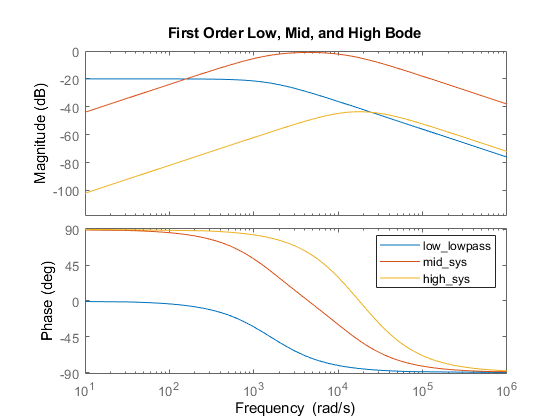

mid_sys = mid_highpass*mid_lowpass;
high_sys = high_highpass*high_lowpass;

bode(low_lowpass);
hold on
bode(mid_sys);
bode(high_sys);
title("First Order Low, Mid, and High Bode");
legend
hold off

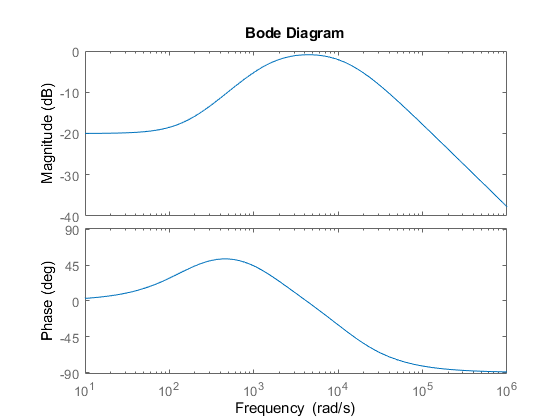


full_sys = low_lowpass + mid_sys + high_sys;
bode(full_sys);

## Second Order Version

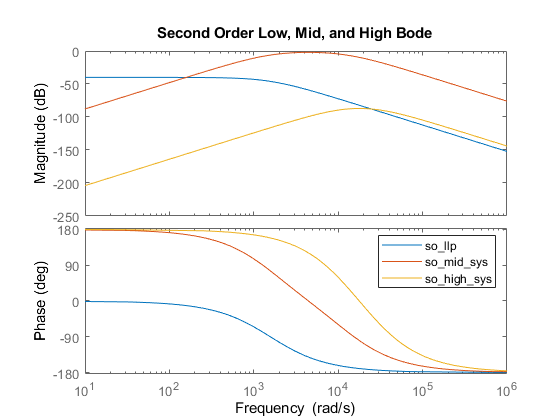

so_llp = low_lowpass^2;
so_mhp = mid_highpass^2;
so_mlp = mid_lowpass^2;
so_hhp = high_highpass^2;
so_hlp = high_lowpass^2;

so_mid_sys = so_mhp*so_mlp;
so_high_sys = so_hhp*so_hlp;

bode(so_llp);
hold on
bode(so_mid_sys);
bode(so_high_sys);
title("Second Order Low, Mid, and High Bode");
legend
hold off


so_full_sys = so_llp + so_mid_sys + so_high_sys;


## Comparing Bode Diagrams

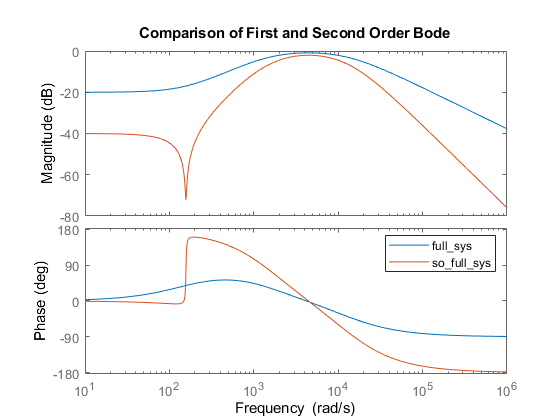

bode(full_sys);
hold on
bode(so_full_sys);
title("Comparison of First and Second Order Bode");
legend
hold off